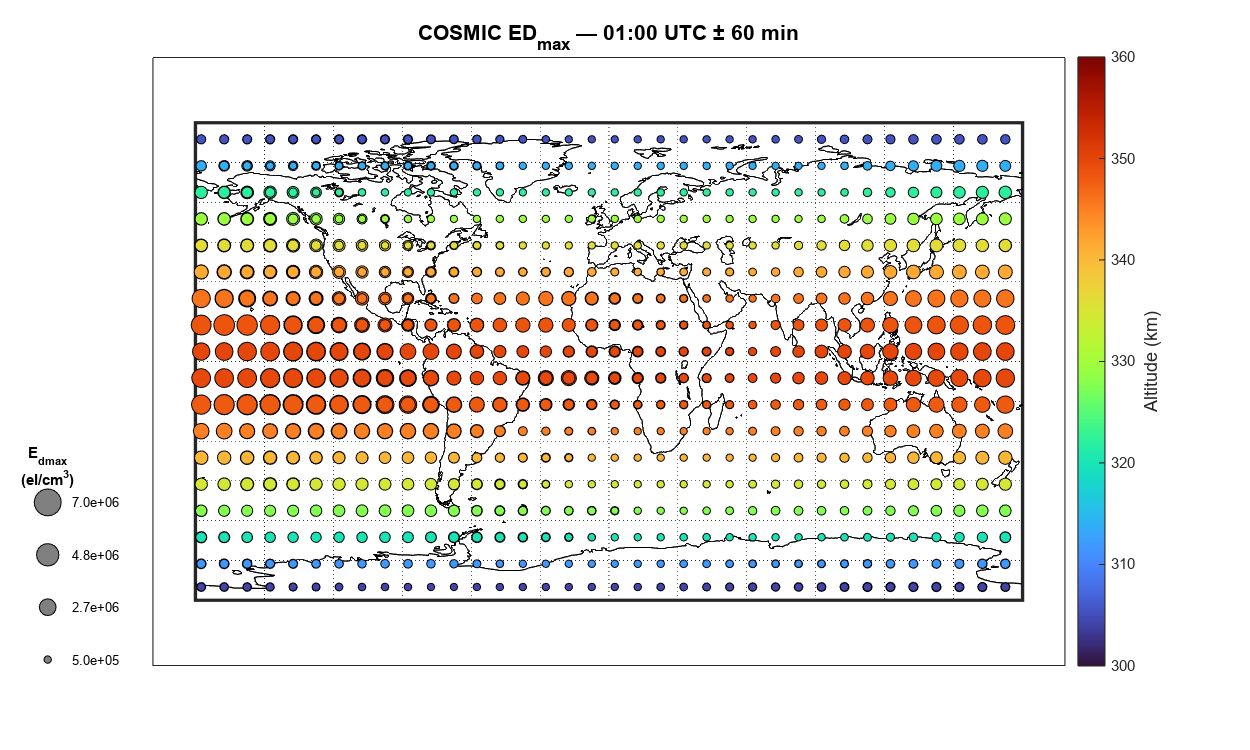

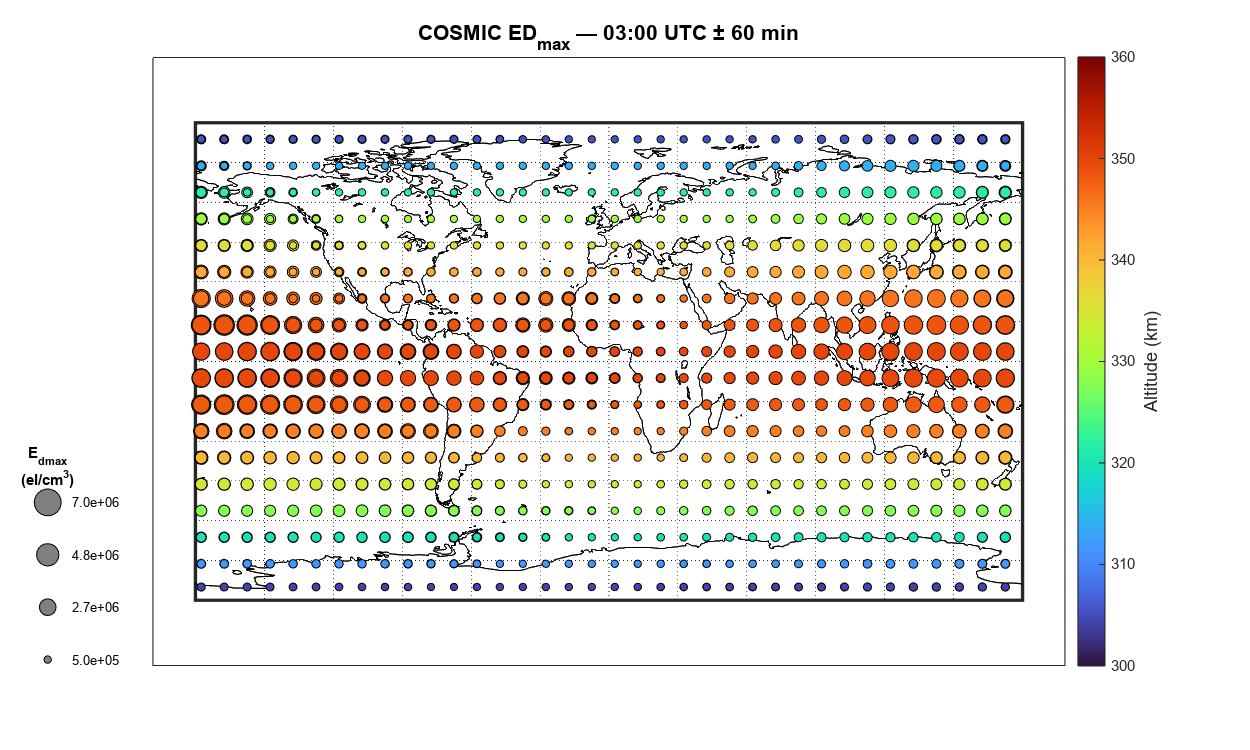

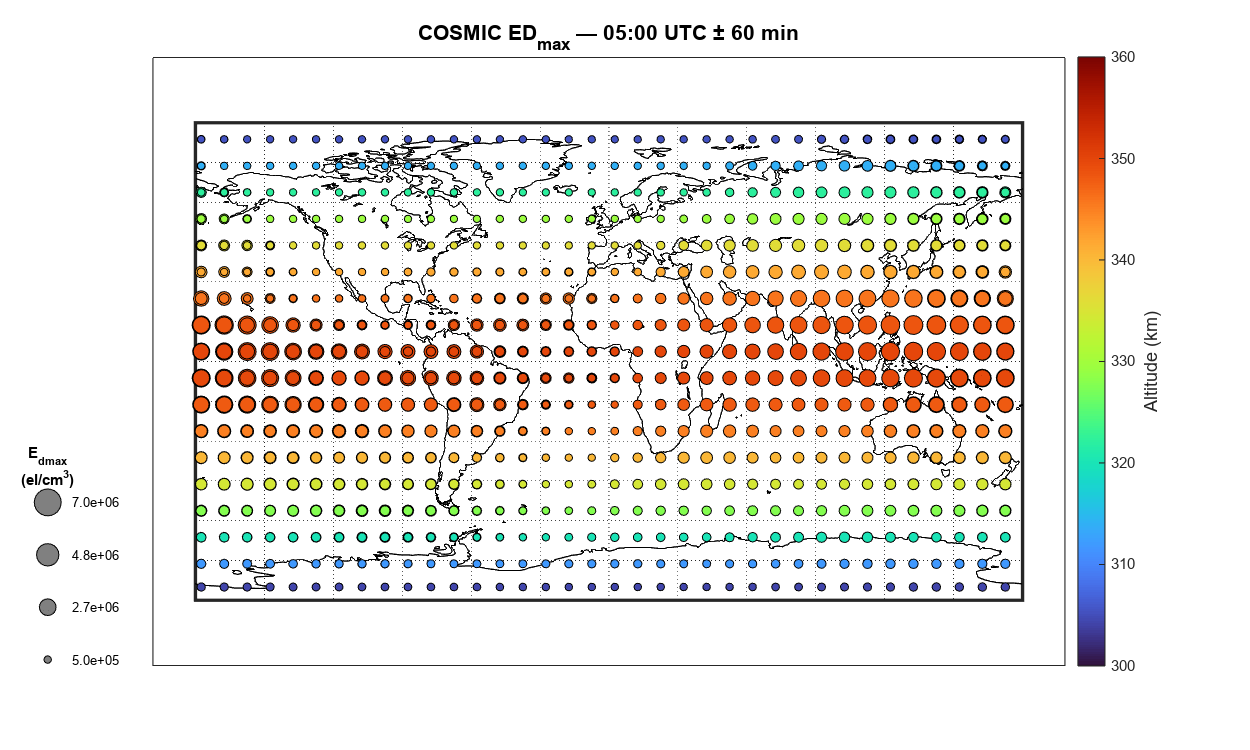

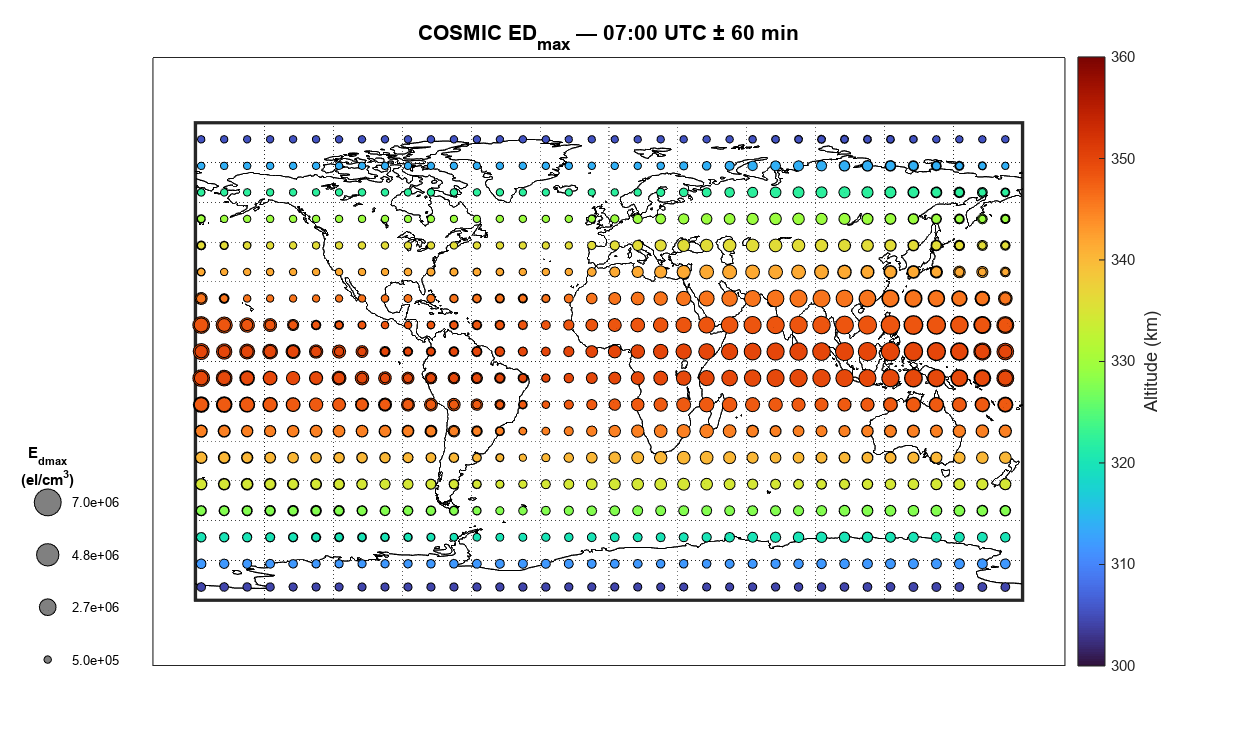

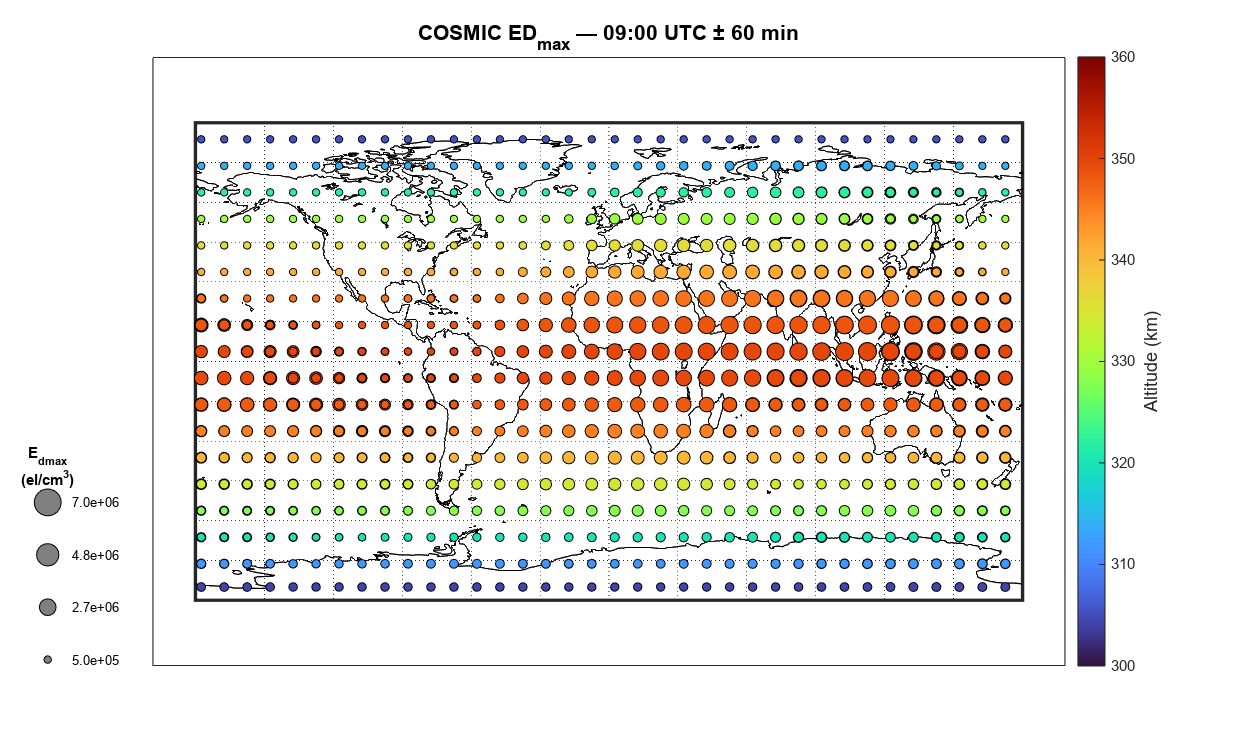

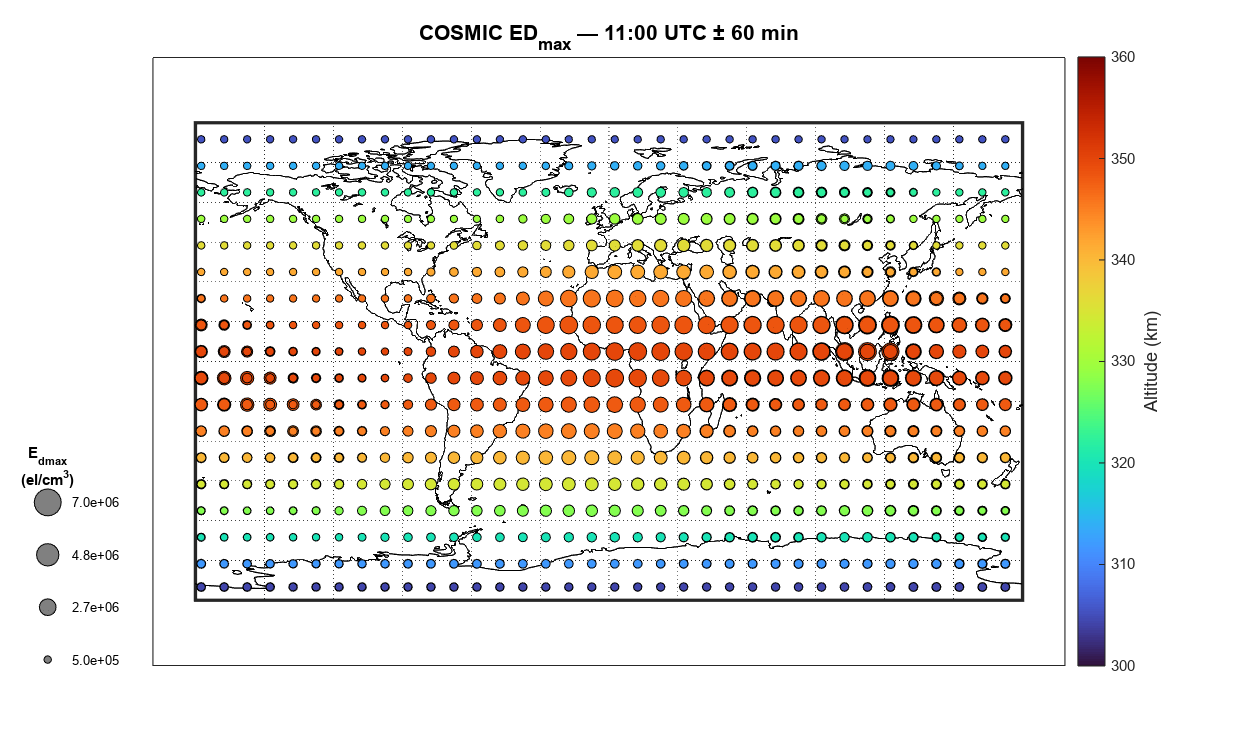

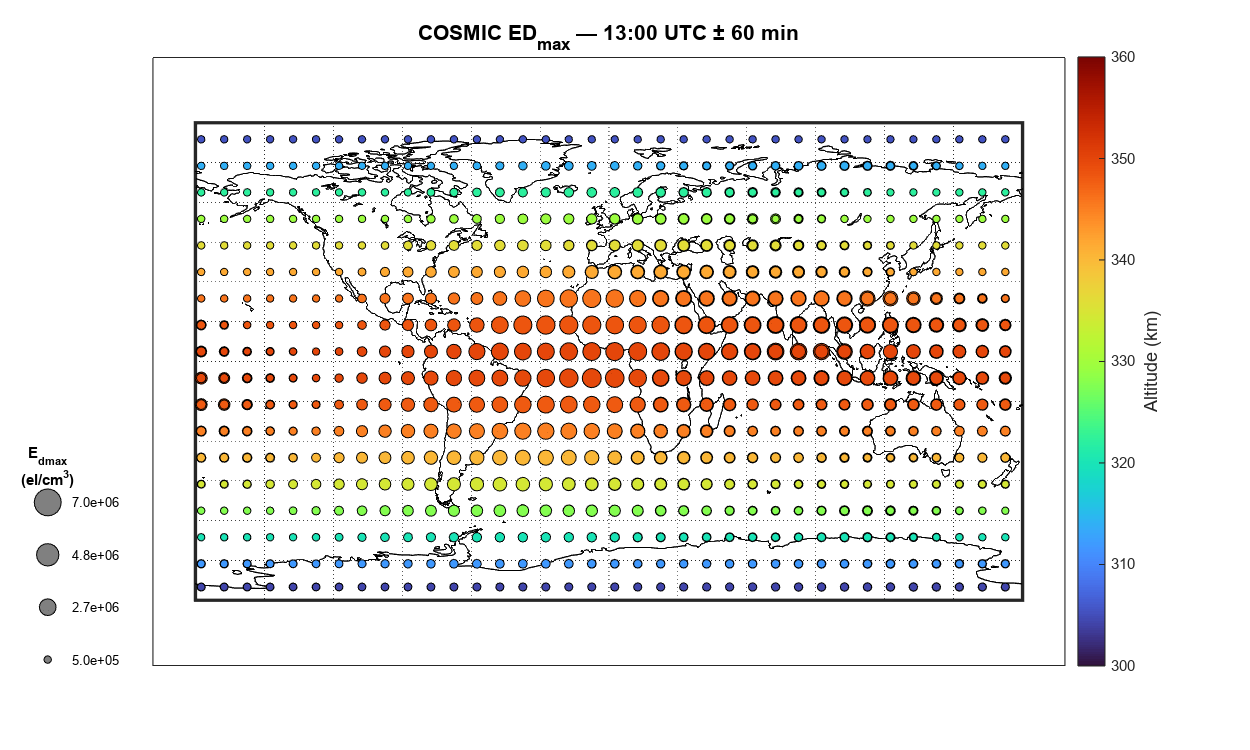

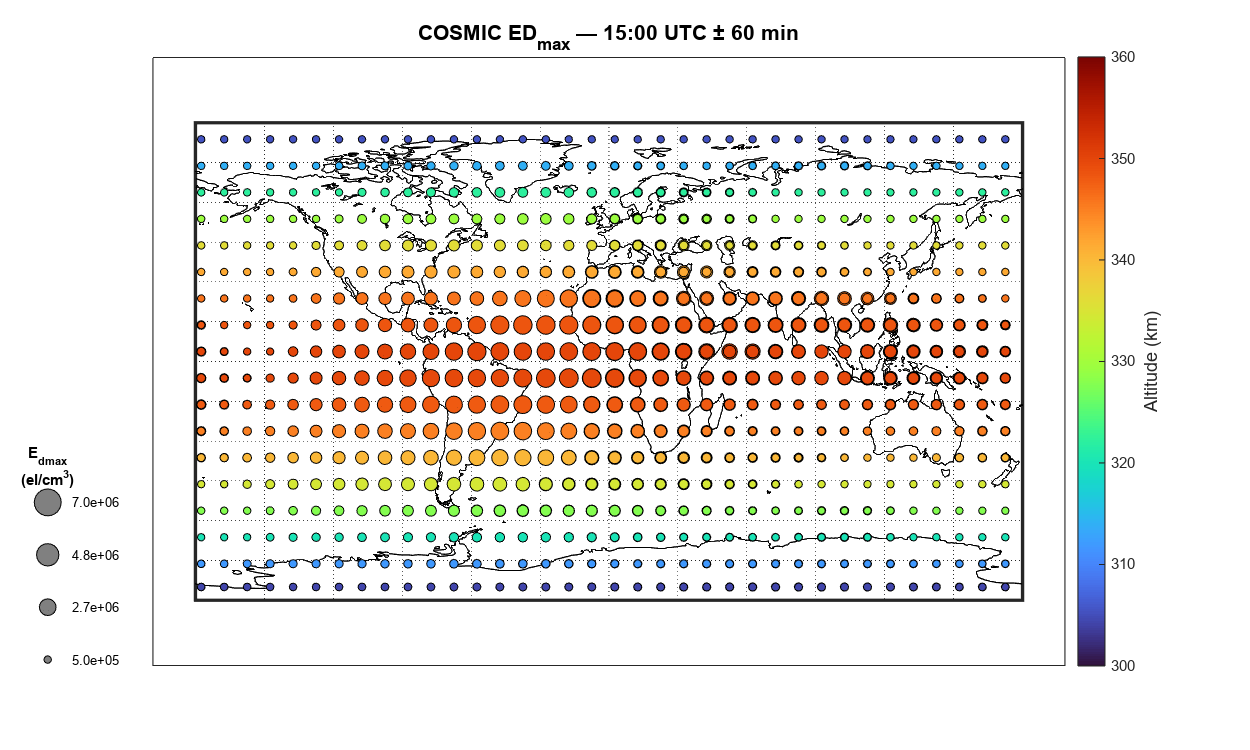

%% COSMIC Electron Density Bubble Map on Globe
% Bubble size = edmax, Bubble colour = altitude
clear min

%USER PARAMETERS
filter_quartiles  = false;
lower_pct         = 5;
upper_pct         = 95;


ED_MIN = 5e5;  
ED_MAX = 7e6;  
SIZE_MIN = 20; 
SIZE_MAX = 260; 


for target_hour = 1:2:23
    target_minute  = 00;
    time_tolerance = 60;

    epoch   = datetime(1980, 1, 6, 0, 0, 0, 'TimeZone', 'UTC');
    all_lat   = [];
    all_lon   = [];
    all_edmax = [];
    all_alt   = [];

    for i = 1:length(COSMIC_data)
        if isnumeric(COSMIC_data{i}.edmaxtime)
            COSMIC_data{i}.edmaxtime = epoch + seconds(COSMIC_data{i}.edmaxtime - 18);
        end

        file_hour          = hour(COSMIC_data{i}.edmaxtime);
        file_min           = minute(COSMIC_data{i}.edmaxtime);
        file_total_minutes = file_hour * 60 + file_min;
        target_total_minutes = target_hour * 60 + target_minute;

        if abs(file_total_minutes - target_total_minutes) > time_tolerance
            continue
        end

        lat = COSMIC_data{i}.edmaxlat;
        lon = COSMIC_data{i}.edmaxlon;
        ed  = COSMIC_data{i}.edmax;
        alt = COSMIC_data{i}.edmaxalt;

        if isempty(lat) || isempty(lon) || isempty(ed) || isempty(alt), continue; end
        if isnan(lat)   || isnan(lon)   || isnan(ed)   || isnan(alt),   continue; end

        all_lat   = [all_lat;   lat];
        all_lon   = [all_lon;   lon];
        all_edmax = [all_edmax; ed];
        all_alt   = [all_alt;   alt];
    end

    if isempty(all_lat)
        warning('No points found within the time window.');
        continue
    end

    %Quartile filter
    if filter_quartiles
        q_low  = prctile(all_alt, lower_pct);
        q_high = prctile(all_alt, upper_pct);
        keep   = all_alt >= q_low & all_alt <= q_high;
        all_lat   = all_lat(keep);
        all_lon   = all_lon(keep);
        all_edmax = all_edmax(keep);
        all_alt   = all_alt(keep);
        fprintf('Hour %02d: kept %d / %d points (%.0f–%.0f pctile)\n', ...
            target_hour, sum(keep), length(keep), lower_pct, upper_pct);
    end

    if isempty(all_lat)
        warning('No points remain after quartile filter for hour %02d.', target_hour);
        continue
    end

    %Normalise
    sz_norm     = (all_edmax - ED_MIN) ./ (ED_MAX - ED_MIN);
    sz_norm     = max(0, min(1, sz_norm));  
    bubble_size = SIZE_MIN + sz_norm * (SIZE_MAX - SIZE_MIN);
    cdata       = all_alt; 

    %Figure
    figure('Color', 'w', 'Position', [100 100 1000 600]);
    clf
    axesm('eqdcylin', 'MapLatLimit', [-90 90], 'MapLonLimit', [-180 180], ...
          'Frame', 'on', 'Grid', 'on')
    load coastlines
    geoshow(coastlat, coastlon, 'Color', 'k', 'LineWidth', 0.8)
    hold on

    %Sort by altitude
    [~, sort_idx] = sort(cdata, 'ascend');
    all_lat     = all_lat(sort_idx);
    all_lon     = all_lon(sort_idx);
    bubble_size = bubble_size(sort_idx);
    cdata       = cdata(sort_idx);

    scatterm(all_lat, all_lon, bubble_size, cdata, 'filled', ...
        'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'k', 'LineWidth', 0.3);
    %Colorbar
    colormap("turbo")
    cb = colorbar;
    if mission_name == 'ground'
        alt_min_all = 300;
        alt_max_all = 360;
    else
        alt_min_all = 200;
        alt_max_all = 550;
    end
    clim([alt_min_all, alt_max_all])
    cb.Label.String  = 'Altitude (km)';
    cb.Label.FontSize = 11;
    title(sprintf('COSMIC ED_{max} — %02d:%02d UTC ± %d min', ...
        target_hour, target_minute, time_tolerance), ...
        'FontSize', 13, 'FontWeight', 'bold')

    %Electron density size
    ed_min_leg = 5e5;
    ed_max_leg = 6e6;
    legend_eds = linspace(ED_MIN, ED_MAX, 4);
    legend_sz  = SIZE_MIN + ((legend_eds - ED_MIN) ./ (ED_MAX - ED_MIN)) * (SIZE_MAX - SIZE_MIN);

    leg_ax = axes('Position', [0.01 0.05 0.10 0.35], ...
        'Visible', 'off');
    hold(leg_ax, 'on')

    for k = 1:length(legend_eds)
        scatter(leg_ax, 0.5, k, legend_sz(k), [0.5 0.5 0.5], 'filled', ...
            'MarkerEdgeColor', 'k', 'LineWidth', 0.5)
        text(leg_ax, 0.85, k, sprintf('%.1e', legend_eds(k)), ...
            'FontSize', 8, 'VerticalAlignment', 'middle')
    end
    
    text(leg_ax, 0.5, length(legend_eds) + 0.7, {'E_{dmax}', '(el/cm^3)'}, ...
        'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'center')

    xlim(leg_ax, [0 1.8])
    ylim(leg_ax, [0 length(legend_eds) + 1])
    hold off
end


while true; end